# Ejercicio 2

Fernando Estrada Silva // A01736094

Considerando el siguiente robot, calcular la velocidad angular y lineal. 

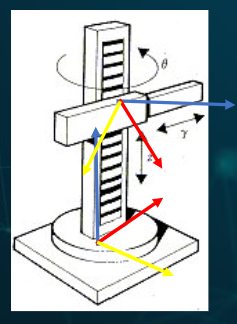

Para dar solución al problema, debe considerarse que este robot cuenta con ambos tipos de juntas: una rotacional y 2 prismáticas. Por lo tanto, debe realizarse un análisis distinto a los que se han abordado en las otras clases. 

Observando la imagen, se puede decir que para el primer y segundo grado de libertad, se tiene el mismo punto de referencia, unicamente con una traslación sobre z. Sin embargo, el sistema cambia cuando se pasa del segundo a tercera junta, dando un giro de -90° sobre el el eje x. Este cambio resultará en modificaciones sobre la matriz de rotación para dichas juntas. 

**Metodología**

En primera instancia, deben declararse las variables simbólicas del programa. Dada la combinación mencionada de juntas, se utiliza un ángulo para la primera articulación y 2 variaciones de longitud para las otras 2. Por eso mismo, el vector RP utiliza un solo 1 y dos 0. 

%Declaración de variables simbólicas
syms l1(t) l2(t) th1(t) t h

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 1 1];

%Creamos el vector de coordenadas articular es
Q= [th1 l1, l2];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);

Ahora, considerando los sistemas de referencia y, que la primera articulación es rotacional, se declara un vector de posición con unicamente traslación sobre z, la cual puede ser variable y despreciable para el análisis, por lo que se declara como una longitud h. Tomando en cuenta que esta articulación rota con respecto al eje z, se colola su matriz de rotación correspondiente. 

%Articulacion 1 
%posicion de la junta 1 respecto a 0
P(:,:,1) = [0;
            0; 
            h];  %vector de posicion indexado por pagina

% Definir la matriz de rotación original R(:,:,1), rotacion en z
R(:,:,1) = [cos(th1) -sin(th1) 0; 
            sin(th1) cos(th1) 0; 
             0           0     1];

Para la segunda articulación, ahora prismática, se debe considerar la rotación del sistema de referencia con respecto al anterior. Considerando una rotación de -90 grados con respecto al eje Z, se plantea un nuevo sistema a partir del cual también se obtiene una nueva matriz de rotación. Se mantiene la matriz identidad dado que no hay más juntas. 

%Articulación 2
%posicion de la junta 3 respecto a 2
P(:,:,2) = [0;0;l1];

R(:,:,2) = [1  0 0;
           0  0 1;
           0 -1 0];


Para la tercera articulación, siendo también prismática se debe considerar la rotación del sistema de referencia con respecto al anterior. Se mantiene la matriz identidad. 

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0 ;l2];
 
R(:,:,3)= [1  0  0;
           0  1  0;
           0  0  1]; %se mantiene la matriz

**Resultados**

Finalmente, se obtienen como resultados: